#      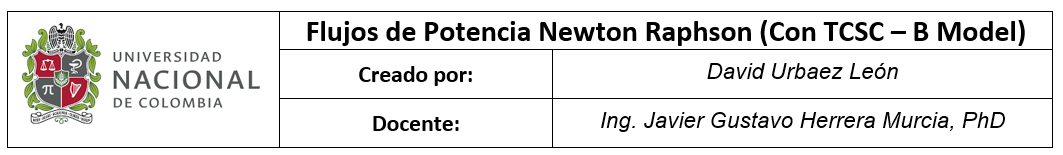

### 1)    Se definen las bases del sistema

-  Potencia base $S_b ={100\cdot 10}^{6\;}$[VA]

-  Voltaje base   $V_b ={230\cdot 10}^{3\;}$[V]

Sb = 100e6; %[VA]
Vb = 230e3; %[V]

### 2)    Se crean las matrices  con la información de la red ( br_data, N_data):

Se deben crear dos matrices para ingresar la información referente al circuito. La primera (br_data) brinda información acerca de las conexiones entre buses como la impedancia de la línea o los buses entre los cuales se realiza la conexión , mientras que la segunda (N_data) da información acerca de la naturaleza de cada uno de los buses, tipo de bus (SL, PV o PQ).

a) Para la matriz **br_data** se tiene que el formato es

                    
$$\mathrm{br}_\mathrm{data}=\left\lbrack {\mathrm{Bus}}_{\mathrm{from}\;} ,{\mathrm{Bus}}_{\mathrm{to}} ,R,X,G,B\right\rbrack \;\mathrm{in}\;p\ldotp u\ldotp$$


b) Para la matriz **N_data **se tiene que el formato es:

                  
$$N_‾‾\mathrm{data}=\left\lbrace \mathrm{#Bus},\mathrm{type}\left(\prime \mathrm{SL}\prime ,\prime \mathrm{PQ}\prime ,\prime \mathrm{PV}\prime \right),V\left\lbrack p\ldotp u\ldotp \right\rbrack ,\angle \mathrm{Vº},\mathrm{PG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{PL}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QL}\left\lbrack p\ldotp u\ldotp \right\rbrack \right\rbrace$$


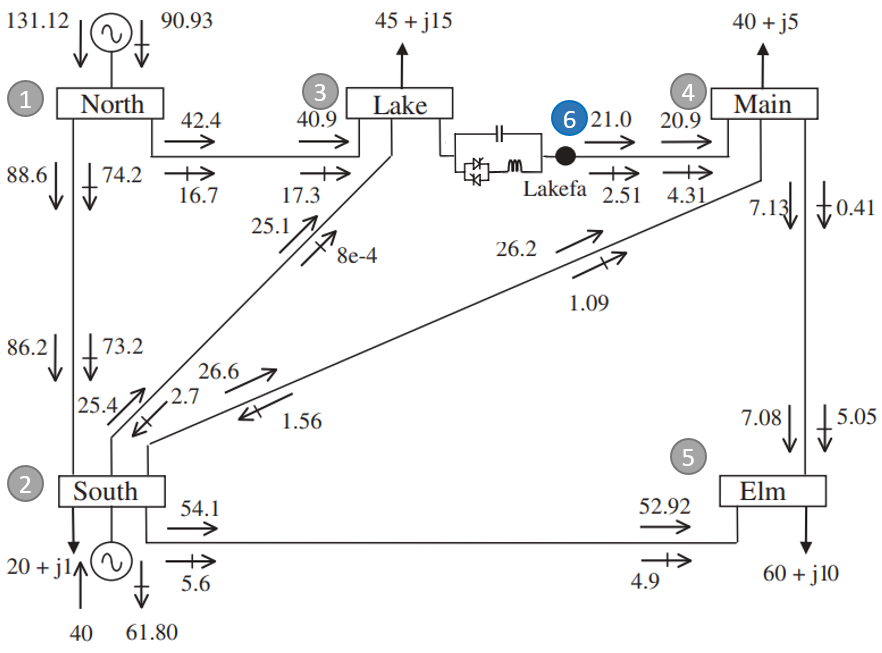

% Branches data R, X, G, B
% Types: General in form of impedance. (G & B are split in half at both ends).

     


% Node definitions
% {  #, type,   Vpu,    <Vº,   PG pu,  QG pu,  PL pu, QL pu}
N_data = {
    1,  'SL',   1.06,   0.0,    0.0,    0.0,    0.00,    0.00;
    2,  'PV',   1.0,    0.0,    0.4,    0.0,    0.20,    0.10;
    3,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.45,    0.15;
    4,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.40,    0.05;
    5,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.60,    0.10;
    6,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.00,    0.00 }; % Se crea el nodo 6 (Lakefa)


% br_data=[ bus1, bus2,   R ,      X ,     G ,     B  ] in p.u.
br_data = [ 1,      2,  0.02,    0.06,    0.0,    0.06;
            1,      3,  0.08,    0.24,    0.0,    0.05;
            2,      3,  0.06,    0.18,    0.0,    0.04;
            2,      4,  0.06,    0.18,    0.0,    0.04;
            2,      5,  0.04,    0.12,    0.0,    0.03;
            6,      4,  0.01,    0.03,    0.0,    0.02;  % || Se modifica la conexión nodo 3-4 a 6-4 ||
            4,      5,  0.08,    0.24,    0.0,    0.05];
        

br_data=array2table(br_data,'VariableNames',{'FromBus','ToBus','R','X','G','B'});
N_data=cell2table(N_data,'VariableNames',{'n','type','Vm','Va','PG','QG','PL','QL'});

% THYRISTOR CONTROLLED SERIES COMPENSATOR reactance variable
% NTCSC : Number of TCSC’s
% TCSCsend : Sending bus
% TCSCrec : Receiving bus
% X : TCSC’s reactance
% XLo : Lower reactance limit
% XHi : Higher reactance limit
% Flow : Power flow direction: 1 is for sending to receiving bus; -1
% indicates opposite direction
% Psp : Active power flow to be controlled
% status : Indicates control status for active power: 1 is on and 0 is off

% TCSC_data= [TCSCsend,TCSCrec,     X  ,  XLo  ,   XHi ,  Psp  , Flow, status];
TCSC_data  = [    3   ,   6   , -0.015 , -0.05 ,  0.05 ,  0.21 ,   1 ,   1   ];

TCSC_data=array2table(TCSC_data,'VariableNames',{'TCSCsend','TCSCrec','X','Xmin','Xmax','Psp','Flow','Status'})

TCSC_data = 1×8 table
    TCSCsend    TCSCrec      X       Xmin     Xmax    Psp     Flow    Status
    ________    _______    ______    _____    ____    ____    ____    ______

       3           6       -0.015    -0.05    0.05    0.21     1        1   


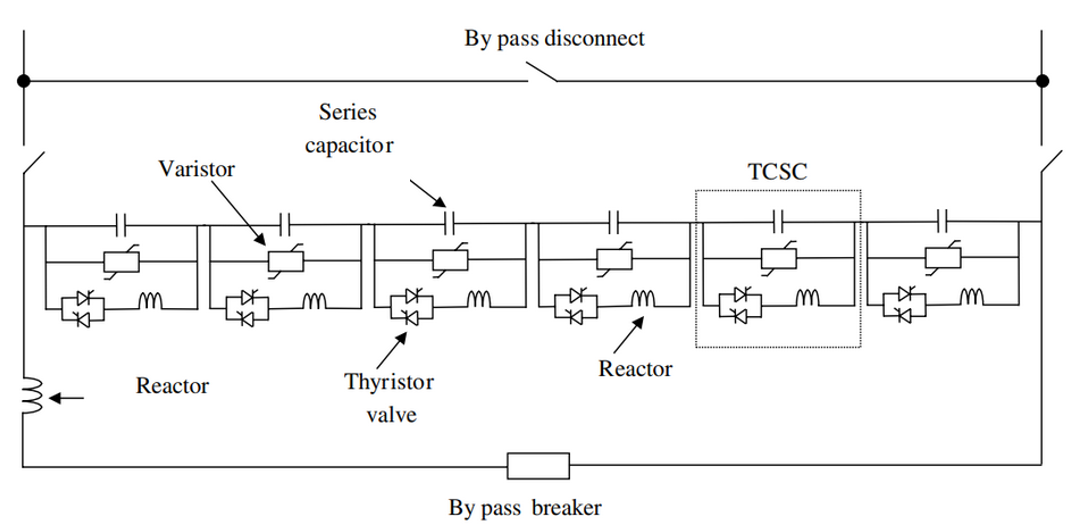(Fig 2.6 - Pag 19, Acha)

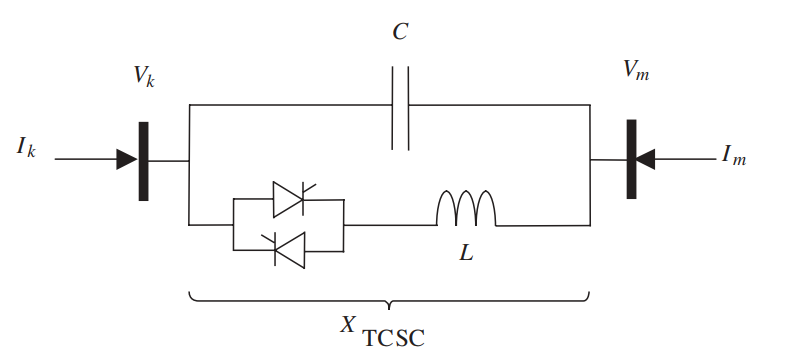(Fig 2.12 - Pag 27, Acha)        

Act_Power=0.4:0.01:1;

V_out=[];
S_out=[];

for status=[0,1]
for index=1:length(Act_Power)

    
    N_data{5,'PL'}=Act_Power(index);
    
    TCSC_data.Status=status;
    Run_TCSC_PowerFlow   
    
            %% Se guardan variables
    V_out=[V_out Vn];
    
    if index==1
        %S_out=[S_out S_pf];
        S_out=array2table(S_pf,'VariableNames',{'FromBus','ToBus','P_1','Q_1','S_1'});
    else
        %S_out=[S_out S_pf(:,3:end)];
        S_out{:, ['P_',num2str(index)]}=S_pf(:,3);
        S_out{:, ['Q_',num2str(index)]}=S_pf(:,4);
        S_out{:, ['S_',num2str(index)]}=S_pf(:,5);
    end
end


### 7) Se presentan los resultados obtenidos

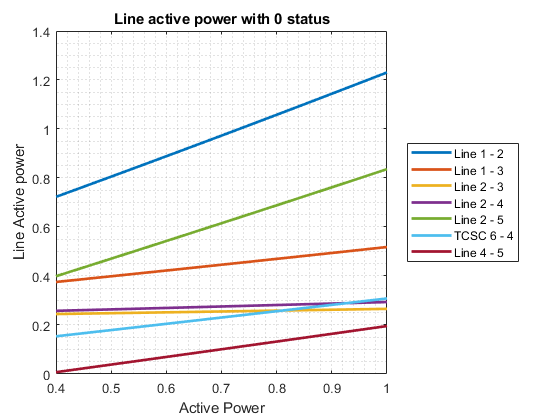

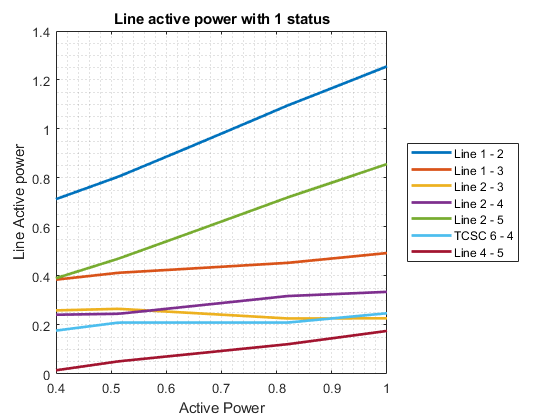


plot(Act_Power,S_out{1:2:end,3:3:end},'LineWidth',2)
 legend('Line 1 - 2',...
        'Line 1 - 3',...
        'Line 2 - 3',...
        'Line 2 - 4',...
        'Line 2 - 5',...
        'TCSC 6 - 4',...
        'Line 4 - 5', 'Location','eastoutside')
grid minor
xlabel('Active Power')
ylabel('Line Active power')
title(['Line active power with ',num2str(status),' status']) 

end   

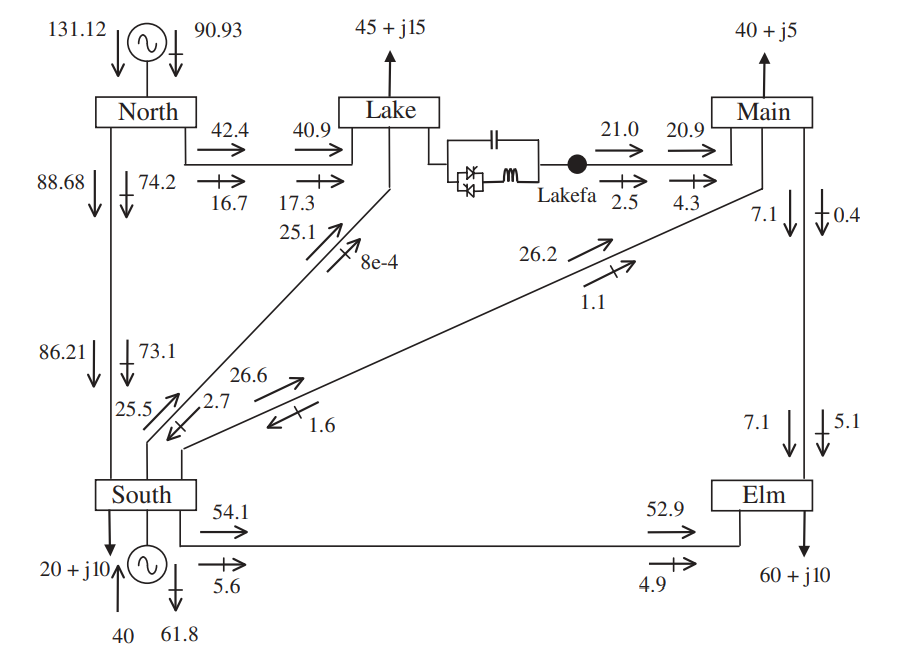

### Referencias:

[1] Gomez - Exposito,A. Electrica Energy Systems, Analysis and operation. 2nd Edition. Boca Raton : Taylor & Francis, CRC Press, 2018.

[2] Acha,E. FACTS Modelling and Simulation in Power Networks. 1st Edition. Boca Raton : John Wiley & Sons Inc,2004 